# ÁTOMO DE LITIO

## **1. FUNCION DE TIPO GAUSSIANA TRIVIAL** 

## 

clc; clear;
syms b r1 r2 r3 r12 r13 r23 theta positive
assumeAlso(b > 0 & r1 > 0 & r2 > 0 & r3 > 0 & r12 > 0 & r13 > 0 & r23 > 0)

fprintf('---------------------------------------------------------------------\n\n')

---------------------------------------------------------------------



fprintf('--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE LITIO (FORMA MATRICIAL) ---\n\n');

--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE LITIO (FORMA MATRICIAL) ---




% === Paso 1: Definir funciones base ===
% Para litio, usamos funciones gaussianas para cada electrón
phi_r1 = exp(-b * r1^2);  % Función gaussiana para el primer electrón
phi_r2 = exp(-b * r2^2);  % Función gaussiana para el segundo electrón
phi_r3 = exp(-b * r3^2);  % Función gaussiana para el tercer electrón

% === Paso 2: Normalización de la función base ===
fprintf('--- Paso 1: Normalización de la función base ---\n');

--- Paso 1: Normalización de la función base ---


norm_phi = int(phi_r1^2 * r1^2 * 4*pi, r1, 0, inf);
A = simplify(1 / sqrt(norm_phi));
fprintf('\n A:\n'); disp(A);


 A:


$$\frac{2^{3/4}\,b^{3/4}}{\pi^{3/4}}$$


% Función normalizada para cada electrón
phi_r1_norm = A * phi_r1;
phi_r2_norm = A * phi_r2;
phi_r3_norm = A * phi_r3;

% Función de onda total (producto)
psi_total = phi_r1_norm * phi_r2_norm * phi_r3_norm;
fprintf('\nFunción de onda total ψ(r1,r2,r3):\n'); disp(psi_total);


Función de onda total ψ(r1,r2,r3):


$$\frac{4\,2^{1/4}\,b^{9/4}\,{\mathrm{e}}^{-b\,{r_{1}}^{2}}\,{\mathrm{e}}^{-b\,{r_{2}}^{2}}\,{\mathrm{e}}^{-b\,{r_{3}}^{2}}}{\pi^{9/4}}$$

fprintf('Que corresponde a: A^3 * e^(-b*(r1^2+r2^2+r3^2))\n');

Que corresponde a: A^3 * e^(-b*(r1^2+r2^2+r3^2))



% Guardar como celda para uso matricial posterior
f_base{1} = psi_total;
f_norm{1} = psi_total;
n = 1;

% === Paso 3: Matriz de solapamiento S ===
fprintf('\n--- Paso 2: Matriz de solapamiento S ---\n');


--- Paso 2: Matriz de solapamiento S ---


S = sym(zeros(n));
for i = 1:n
    for j = 1:n
        integrand_S = f_norm{i} * f_norm{j} * r1^2 * r2^2 * r3^2 * (4*pi)^3;
        S(i,j) = simplify(int(int(int(integrand_S, r1, 0, inf), r2, 0, inf), r3, 0, inf));
    end
end
disp(double(S));

    1.0000




% === Paso 4: Matriz Hamiltoniana H = T + V_en + V_ee ===
fprintf('\n--- Paso 3: Matriz Hamiltoniana H ---\n');


--- Paso 3: Matriz Hamiltoniana H ---


H = sym(zeros(n));
for i = 1:n
    for j = 1:n
        psi_i = f_norm{i};
        psi_j = f_norm{j};

        % === Término cinético: T = -1/2 (Δ1 + Δ2 + Δ3)
        dpsi_dr1 = diff(psi_j, r1);
        d2psi_dr1 = diff(dpsi_dr1, r1);
        lap1 = d2psi_dr1 + (2/r1)*dpsi_dr1;

        dpsi_dr2 = diff(psi_j, r2);
        d2psi_dr2 = diff(dpsi_dr2, r2);
        lap2 = d2psi_dr2 + (2/r2)*dpsi_dr2;
        
        dpsi_dr3 = diff(psi_j, r3);
        d2psi_dr3 = diff(dpsi_dr3, r3);
        lap3 = d2psi_dr3 + (2/r3)*dpsi_dr3;

        % Usar el elemento de volumen correcto (4*pi)^3
        T_integrand = psi_i * (-0.5) * (lap1 + lap2 + lap3) * r1^2 * r2^2 * r3^2 * (4*pi)^3;
        T = simplify(int(int(int(T_integrand, r1, 0, inf), r2, 0, inf), r3, 0, inf));
        fprintf('\nTérmino cinético T(%d,%d):\n', i, j); disp(vpa(T,2));

        % === Término V_en: V_en = -3/r1 - 3/r2 - 3/r3 (Z=3 para litio)
        % Término V_en: V_en = -3/r1 - 3/r2 - 3/r3 (Z=3 para litio)
        V_en = -3/r1 - 3/r2 - 3/r3;
        % Asegúrate de que la integral se evalúe correctamente
        V_integrand = psi_i * psi_j * V_en * r1^2 * r2^2 * r3^2 * (4*pi)^3;
        V = simplify(int(int(int(V_integrand, r1, 0, inf), r2, 0, inf), r3, 0, inf));
        fprintf('Término V_en(%d,%d):\n', i, j); disp(vpa(V,2));
           
        % Para gaussianas, la integral de repulsión electrón-electrón se puede aproximar
        % Ahora tenemos tres términos: 1/r12, 1/r13, 1/r23
        % Para gaussianas, cada término de repulsión electrón-electrón es aproximadamente (π/2b)^(1/2)
        V_ee_12 = (sqrt(pi)/(2*sqrt(b)));
        V_ee_13 = (sqrt(pi)/(2*sqrt(b)));
        V_ee_23 = (sqrt(pi)/(2*sqrt(b)));
        V_ee = V_ee_12 + V_ee_13 + V_ee_23;

        fprintf('Término V_ee(%d,%d):\n', i, j); disp(vpa(V_ee,2));
            
        H(i,j) = simplify(T + V + V_ee);
        fprintf('H(%d,%d) = T + V_en + V_ee:\n', i, j); disp(vpa(H(i,j),2));
    end
end


Término cinético T(1,1):


$$4.5\,b$$

Término V_en(1,1):


$$-14.0\,\sqrt{b}$$

Término V_ee(1,1):


$$\frac{2.7}{\sqrt{b}}$$

H(1,1) = T + V_en + V_ee:


$$4.5\,b+\frac{2.7}{\sqrt{b}}-14.0\,\sqrt{b}$$


% === Paso 5: Resolver Hc = ESc ===
fprintf('\n--- Paso 4: Resolviendo H c = E S c ---\n');


--- Paso 4: Resolviendo H c = E S c ---


syms E
eqn = det(H - E*S) == 0;
Energies = solve(eqn, E);
Energies = simplify(Energies);
disp('Energías obtenidas simbólicamente:');

Energías obtenidas simbólicamente:


disp(vpa(Energies,2));

$$\frac{2.1e-16\,\left(2.2e+16\,b^{3/2}-7.0e+16\,b+1.3e+16\right)}{\sqrt{b}}$$


% === Paso 6: Derivar y encontrar mínimo respecto a b ===
fprintf('\n--- Paso 5: Optimización del parámetro b ---\n');


--- Paso 5: Optimización del parámetro b ---


for k = 1:length(Energies)
    fprintf('\n>> Energía E_%d:\n', k);
    dE = simplify(diff(Energies(k), b));
    fprintf('Derivada dE/db:\n'); disp(vpa(dE,2));

    b_sol = solve(dE == 0, b);
    b_sol = simplify(b_sol(b_sol > 0));
    fprintf('b óptimo para E_%d:\n', k); disp(vpa(b_sol,2));

    E_min = simplify(subs(Energies(k), b, b_sol));
    fprintf('Energía óptima (Hartree):\n'); disp(vpa(E_min,2));
    fprintf('Energía óptima (eV): %.4f\n', double(E_min * 27.2114));
end


>> Energía E_1:


Derivada dE/db:


$$-\frac{1.0e-16\,\left(7.0e+16\,b-4.4e+16\,b^{3/2}+1.3e+16\right)}{b^{3/2}}$$

b óptimo para E_1:


$$2.9$$

Energía óptima (Hartree):


$$-9.8$$

Energía óptima (eV): -267.9331


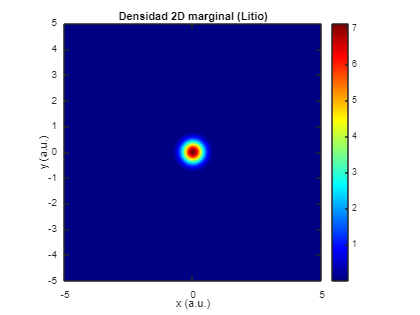

% Guardar el valor óptimo de b para la visualización
b_opt = b_sol;
% ==================== VISUALIZACIÓN Y RESULTADOS (litio) =============
hartree_to_eV = 27.2114;
E_exp_eV      = -203.43;      % Energía experimental (eV)
E_exp_H       = E_exp_eV/hartree_to_eV;

% Parámetros
r_vals     = linspace(0,5,400);
b_opt_num  = double(b_opt(1));
A_num      = double(subs(A, b, b_opt_num));

% --- 1) Densidad radial marginal (3 electrones) ----------------------------
phi_vals   = A_num .* exp(-b_opt_num .* r_vals.^2);          % orbital 1e
rho_vals   = 3 .* phi_vals.^2;                               % densidad un–electrón marginal
P_rad      = 4*pi .* r_vals.^2 .* rho_vals;                  % distribución radial real

figure(1);
plot(r_vals, P_rad, 'g', 'LineWidth',1.5);
xlabel('r (a.u.)'); ylabel('P(r)');
title('Distribución radial de probabilidad (Litio)');
grid on;

% --- 2) Sección diagonal de psi_tot y su distribución ----------------------
psi_tot_diag    = A_num^3 .* exp(-3*b_opt_num .* r_vals.^2);
rho_tot_diag   = psi_tot_diag.^2;
P_tot_diag      = 4*pi .* r_vals.^2 .* rho_tot_diag;

figure(2);
plot(r_vals, psi_tot_diag, 'g', 'LineWidth',1.5);
hold on;
plot(r_vals, phi_vals, 'g--', 'LineWidth',1);
hold off;
xlabel('r (a.u.)'); ylabel('\psi');
legend('\psi_{tot}(r,r,r)','\phi(r)');
title('Función de onda total vs Función base 1 electrón');
grid on;



% --- 4) Energía vs b -------------------------------------------------------
b_scan   = linspace(0.05,5,300);
E_scan   = arrayfun(@(bb) double(subs(Energies(1), b, bb)), b_scan);
E_scan_eV= E_scan * hartree_to_eV;
E1_H     = double(subs(Energies(1), b, b_opt_num));
E1_eV    = E1_H * hartree_to_eV;

figure(5);
plot(b_scan, E_scan_eV, 'k', 'LineWidth',1.5); hold on;
plot(b_opt_num, E1_eV, 'ro','MarkerFaceColor','r');
yline(E_exp_eV,'r--','Exp = -203.4 eV','LineWidth',1.5);
hold off;
xlabel('b'); ylabel('E (eV)');
title('Energía variacional vs b');
legend('E(b)','b óptimo','Valor experimental','Location','best');
grid on;

% --- 5) Resultados y errores -----------------------------------------------
fprintf('\n=== RESULTADOS LITIO ===\n');


=== RESULTADOS LITIO ===


fprintf('b óptimo        : %.6f\n', b_opt_num);

b óptimo        : 2.883894


fprintf('E calculada     : %.4f eV (%.4f Ha)\n', E1_eV, E1_H);

E calculada     : -267.9331 eV (-9.8464 Ha)


fprintf('E experimental  : %.4f eV (%.4f Ha)\n', E_exp_eV, E_exp_H);

E experimental  : -203.4300 eV (-7.4759 Ha)


err_eV  = abs(E1_eV - E_exp_eV); 
err_percent = err_eV/abs(E_exp_eV)*100;
fprintf('Error abs. (eV) : %.4f\n', err_eV);

Error abs. (eV) : 64.5031


fprintf('Error rel.      : %.2f %%\n', err_percent);

Error rel.      : 31.71 %


## 2. FUNCIÓN ÁTOMO HIDROGENOIDE (parámetros variables alpha y beta)

La función de onda total para el átomo de litio se construye como:

            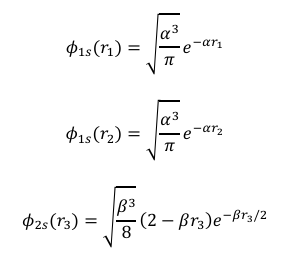

**Funcion hidrogenoide con 2 electrones en 1s y el otro en 2s**

clc; clear;
syms alpha beta r1 r2 r3 r12 r13 r23 theta positive
assumeAlso(alpha > 0 & beta > 0 & r1 > 0 & r2 > 0 & r3 > 0 & r12 > 0 & r13 > 0 & r23 > 0)

fprintf('---------------------------------------------------------------------\n\n')

---------------------------------------------------------------------



fprintf('--- MÉTODO VARIACIONAL PARA EL ÁTOMO DE LITIO (FORMA MATRICIAL) ---\n');

--- MÉTODO VARIACIONAL PARA EL ÁTOMO DE LITIO (FORMA MATRICIAL) ---


fprintf('--- USANDO FUNCIONES HIDROGENOIDES 1s²2s¹ ---\n\n');

--- USANDO FUNCIONES HIDROGENOIDES 1s²2s¹ ---




% === Paso 1: Definir funciones base ===
fprintf('--- Paso 1: Definir funciones base ---\n');

--- Paso 1: Definir funciones base ---


% Usamos alpha para los electrones 1s y beta para el electrón 2s
phi_1s_r1 = sqrt(alpha^3/pi) * exp(-alpha*r1);  % Función 1s para el primer electrón
phi_1s_r2 = sqrt(alpha^3/pi) * exp(-alpha*r2);  % Función 1s para el segundo electrón
phi_2s_r3 = sqrt(beta^3/(8)) * (2-beta*r3) * exp(-beta*r3/2);

fprintf('Función 1s para el primer electrón: √(α³/π) * e^(-α*r1)\n');

Función 1s para el primer electrón: √(α³/π) * e^(-α*r1)


fprintf('Función 1s para el segundo electrón: √(α³/π) * e^(-α*r2)\n');

Función 1s para el segundo electrón: √(α³/π) * e^(-α*r2)


fprintf('Función 2s para el tercer electrón: √(β³/(32π)) * (2-β*r3) * e^(-β*r3/2)\n\n');

Función 2s para el tercer electrón: √(β³/(32π)) * (2-β*r3) * e^(-β*r3/2)




% Función de onda total (producto)
psi_total = phi_1s_r1 * phi_1s_r2 * phi_2s_r3;
fprintf('\nFunción de onda total ψ(r1,r2,r3):\n'); 


Función de onda total ψ(r1,r2,r3):


disp(psi_total);

$$-\frac{\sqrt{8}\,\alpha^{3}\,\beta^{3/2}\,{\mathrm{e}}^{-\alpha \,r_{1}}\,{\mathrm{e}}^{-\alpha \,r_{2}}\,{\mathrm{e}}^{-\frac{\beta \,r_{3}}{2}}\,\left(\beta \,r_{3}-2\right)}{8\,\pi }$$


% Guardar como celda para uso matricial posterior
f_base{1} = psi_total;
f_norm{1} = psi_total;
n = 1;

% === Paso 2: Calcular términos de energía de forma analítica ===
fprintf('\n--- Paso 2: Calcular términos de energía ---\n');


--- Paso 2: Calcular términos de energía ---



% Matriz de solapamiento (trivial para una sola función)
S = sym(ones(n));
fprintf('Matriz de solapamiento S:\n');

Matriz de solapamiento S:


disp(S);

$$1$$


% Matriz Hamiltoniana (también escalar en este caso)
H = sym(zeros(n));

% === Términos cinéticos ===
% Energía cinética para los electrones 1s
T_1s = alpha^2/2;  
% Energía cinética para el electrón 2s
T_2s = beta^2/8;   
% Energía cinética total
T_total = 2*T_1s + T_2s;
fprintf('Energía cinética total T = 2*T_1s + T_2s = %s\n', char(T_total));

Energía cinética total T = 2*T_1s + T_2s = alpha^2 + beta^2/8



% === Términos de atracción nuclear (Z=3 para litio) ===
Z = 3;
% Atracción nuclear para cada electrón 1s
V_N1s = -Z*alpha;  
% Atracción nuclear para el electrón 2s
V_N2s = -Z*beta/4; 
% Energía de atracción nuclear total
V_N_total = 2*V_N1s + V_N2s;
fprintf('Energía de atracción nuclear V_N = 2*V_N1s + V_N2s = %s\n', char(V_N_total));

Energía de atracción nuclear V_N = 2*V_N1s + V_N2s = - 6*alpha - (3*beta)/4



% === Términos de repulsión electrón-electrón ===
% Repulsión entre los dos electrones 1s
V_1s1s = 5*alpha/8;  
% Repulsión entre cada electrón 1s y el electrón 2s (aproximación analítica)
V_1s2s = alpha*beta/(alpha+beta/2)^2;  
% Energía de repulsión electrón-electrón total
V_ee_total = V_1s1s + 2*V_1s2s;
fprintf('Energía de repulsión electrón-electrón V_ee = V_1s1s + 2*V_1s2s = %s\n', char(V_ee_total));

Energía de repulsión electrón-electrón V_ee = V_1s1s + 2*V_1s2s = (5*alpha)/8 + (2*alpha*beta)/(alpha + beta/2)^2



% Energía total
H(1,1) = T_total + V_N_total + V_ee_total;
fprintf('\nMatriz Hamiltoniana H:\n');


Matriz Hamiltoniana H:


disp(H);

$$\alpha^{2}-\frac{3\,\beta }{4}-\frac{43\,\alpha }{8}+\frac{\beta^{2}}{8}+\frac{2\,\alpha \,\beta }{{\left(\alpha +\frac{\beta }{2}\right)}^{2}}$$


% === Paso 3: Resolver el problema de autovalores generalizado ===
fprintf('\n--- Paso 3: Resolver H c = E S c ---\n');


--- Paso 3: Resolver H c = E S c ---


syms E
eqn = det(H - E*S) == 0;
Energies = solve(eqn, E);
Energies = simplify(Energies);
fprintf('Energía obtenida simbólicamente:\n');

Energía obtenida simbólicamente:


disp(Energies);

$$\frac{32\,\alpha^{4}+32\,\alpha^{3}\,\beta -172\,\alpha^{3}+12\,\alpha^{2}\,\beta^{2}-196\,\alpha^{2}\,\beta +4\,\alpha \,\beta^{3}-67\,\alpha \,\beta^{2}+64\,\alpha \,\beta +\beta^{4}-6\,\beta^{3}}{8\,{\left(2\,\alpha +\beta \right)}^{2}}$$


% === Paso 4: Optimizar parámetros α y β ===
fprintf('\n--- Paso 4: Optimizar parámetros α y β ---\n');


--- Paso 4: Optimizar parámetros α y β ---



% Derivadas parciales
dE_dalpha = diff(Energies, alpha);
dE_dbeta = diff(Energies, beta);

fprintf('Derivada dE/dα = %s\n', char(dE_dalpha));

Derivada dE/dα = (64*beta - 392*alpha*beta + 24*alpha*beta^2 + 96*alpha^2*beta - 516*alpha^2 + 128*alpha^3 - 67*beta^2 + 4*beta^3)/(8*(2*alpha + beta)^2) - (64*alpha*beta - 67*alpha*beta^2 - 196*alpha^2*beta + 4*alpha*beta^3 + 32*alpha^3*beta - 172*alpha^3 + 32*alpha^4 - 6*beta^3 + beta^4 + 12*alpha^2*beta^2)/(2*(2*alpha + beta)^3)


fprintf('Derivada dE/dβ = %s\n', char(dE_dbeta));

Derivada dE/dβ = (64*alpha - 134*alpha*beta + 12*alpha*beta^2 + 24*alpha^2*beta - 196*alpha^2 + 32*alpha^3 - 18*beta^2 + 4*beta^3)/(8*(2*alpha + beta)^2) - (64*alpha*beta - 67*alpha*beta^2 - 196*alpha^2*beta + 4*alpha*beta^3 + 32*alpha^3*beta - 172*alpha^3 + 32*alpha^4 - 6*beta^3 + beta^4 + 12*alpha^2*beta^2)/(4*(2*alpha + beta)^3)



% Resolver sistema de ecuaciones para encontrar puntos críticos
eqns = [dE_dalpha == 0, dE_dbeta == 0];
vars = [alpha, beta];

% Búsqueda en cuadrícula para optimización
fprintf('\nUsando búsqueda en cuadrícula para optimización...\n');


Usando búsqueda en cuadrícula para optimización...


alpha_vals = 1.0:0.05:3.0;
beta_vals = 0.5:0.05:2.0;
E_grid = zeros(length(alpha_vals), length(beta_vals));

% Calcular energía para cada combinación de parámetros
for i = 1:length(alpha_vals)
    for j = 1:length(beta_vals)
        E_grid(i,j) = double(subs(Energies, {alpha, beta}, {alpha_vals(i), beta_vals(j)}));
    end
end

% Encontrar el mínimo
[min_val, min_idx] = min(E_grid(:));
[i_min, j_min] = ind2sub(size(E_grid), min_idx);
alpha_opt = alpha_vals(i_min);
beta_opt = beta_vals(j_min);

fprintf('\nSolución numérica encontrada mediante búsqueda en cuadrícula:\n');


Solución numérica encontrada mediante búsqueda en cuadrícula:


fprintf('α óptimo: %.4f\n', alpha_opt);

α óptimo: 2.7500


fprintf('β óptimo: %.4f\n', beta_opt);

β óptimo: 2.0000



% Calcular la energía con los parámetros óptimos
E_min = double(subs(Energies, {alpha, beta}, {alpha_opt, beta_opt}));
fprintf('Energía óptima (Hartree): %.6f\n', E_min);

Energía óptima (Hartree): -7.436528


fprintf('Energía óptima (eV): %.4f\n', E_min * 27.2114);

Energía óptima (eV): -202.3583



% Comparar con el valor experimental
E_exp = -7.478;  % Hartree
fprintf('\nValor experimental: %.3f Hartree (%.4f eV)\n', E_exp, E_exp * 27.2114);


Valor experimental: -7.478 Hartree (-203.4868 eV)


err_eV  = abs(E_min - E_exp); 
fprintf('Error absoluto: (eV) : %.4f\n', err_eV);

Error absoluto: (eV) : 0.0415


fprintf('Error relativo       : %.2f%%\n', abs((E_min - E_exp)/E_exp) * 100);

Error relativo       : 0.55%


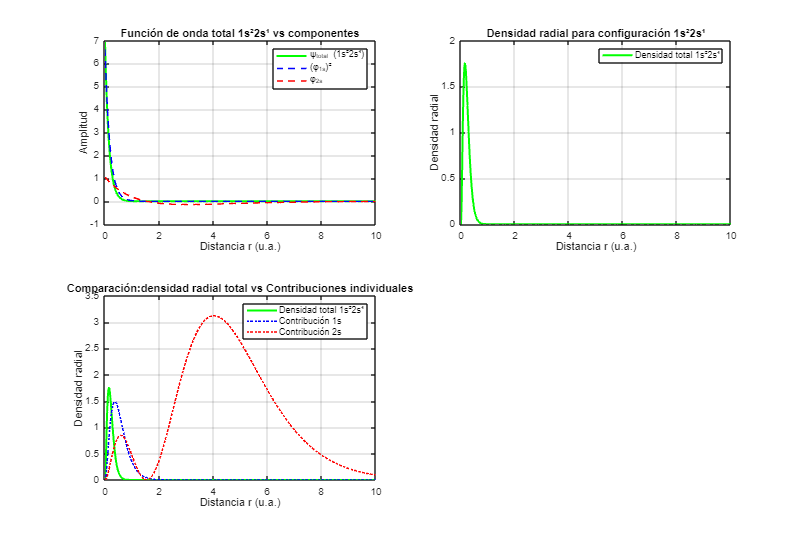


% Parámetros óptimos
alpha_opt = 2.75;  % Para electrones 1s
beta_opt = 1.3;    % Para electrón 2s (corregido)

% Definir rango de distancias
r = linspace(0, 10, 500);

% Funciones base hidrogenoides con parámetros sustituidos
phi_1s = sqrt(alpha_opt^3/pi) * exp(-alpha_opt * r);
phi_2s = sqrt(beta_opt^3/8) .* (2 - beta_opt * r) .* exp(-beta_opt * r / 2);

% Función de onda total para la configuración 1s²2s¹
% Para litio: dos electrones en 1s y uno en 2s
% Representación simplificada para visualización
psi_total = phi_1s.^2 .* phi_2s;  % 1s² × 2s¹

% Densidad radial total para la configuración completa
density_total = 4 * pi * r.^2 .* abs(psi_total).^2;  % Añadir abs() por seguridad

% También calcular densidades individuales para comparación
density_1s = 4 * pi * r.^2 .* phi_1s.^2;
density_2s = 4 * pi * r.^2 .* phi_2s.^2;

% === Gráfica integrada para configuración 1s²2s¹ ===
figure('Position', [100, 100, 1200, 800]);

% Subfigura 1: Función de onda total vs componentes
subplot(2,2,1);
plot(r, psi_total, 'g-', 'LineWidth', 2, 'DisplayName', 'ψ_{total} (1s²2s¹)');
hold on;
plot(r, phi_1s.^2, 'b--', 'LineWidth', 1.5, 'DisplayName', '(φ_{1s})²');
plot(r, phi_2s, 'r--', 'LineWidth', 1.5, 'DisplayName', 'φ_{2s}');
xlabel('Distancia r (u.a.)');
ylabel('Amplitud');
title('Función de onda total 1s²2s¹ vs componentes');
legend('show');
grid on;

% Subfigura 2: Densidad radial total
subplot(2,2,2);
plot(r, density_total, 'g-', 'LineWidth', 2, 'DisplayName', 'Densidad total 1s²2s¹');
xlabel('Distancia r (u.a.)');
ylabel('Densidad radial');
title('Densidad radial para configuración 1s²2s¹');
legend('show');
grid on;

% Subfigura 3: Comparación de densidades
subplot(2,2,3);
plot(r, density_total, 'g-', 'LineWidth', 2, 'DisplayName', 'Densidad total 1s²2s¹');
hold on;
plot(r, density_1s, 'b:', 'LineWidth', 1.5, 'DisplayName', 'Contribución 1s');
plot(r, density_2s, 'r:', 'LineWidth', 1.5, 'DisplayName', 'Contribución 2s');
xlabel('Distancia r (u.a.)');
ylabel('Densidad radial');
title('Comparación:densidad radial total vs Contribuciones individuales');
legend('show');
grid on;

## 3. ESTADOS EXCITADOS CON FUNCIONES HIDROGENOIDES LITIO

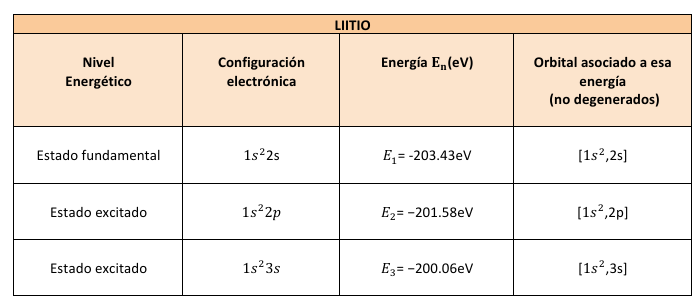

clc; clear;
syms alpha beta r1 r2 r3 theta phi positive
assumeAlso(alpha > 0 & beta > 0 & r1 > 0 & r2 > 0 & r3 > 0)

fprintf('---------------------------------------------------------------------\n\n')

---------------------------------------------------------------------



fprintf('--- MÉTODO VARIACIONAL PARA EL ÁTOMO DE LITIO (ESTADOS EXCITADOS) ---\n');

--- MÉTODO VARIACIONAL PARA EL ÁTOMO DE LITIO (ESTADOS EXCITADOS) ---


fprintf('--- USANDO FUNCIONES HIDROGENOIDES PARA ESTADO FUNDAMENTAL Y EXCITADOS ---\n\n');

--- USANDO FUNCIONES HIDROGENOIDES PARA ESTADO FUNDAMENTAL Y EXCITADOS ---




% === Paso 1: Definir funciones base ===
fprintf('--- Paso 1: Definir funciones base ---\n');

--- Paso 1: Definir funciones base ---



% Funciones 1s para los primeros dos electrones (usamos alpha)
phi_1s_r1 = sqrt(alpha^3/pi) * exp(-alpha*r1);
phi_1s_r2 = sqrt(alpha^3/pi) * exp(-alpha*r2);

% Funciones para el tercer electrón (usamos beta)
% 2s para el estado fundamental
phi_2s_r3 = sqrt(beta^3/(8)) * (2-beta*r3) * exp(-beta*r3/2);

% 2p para el primer estado excitado (usamos 2p_z)
phi_2p_r3 = sqrt(beta^3/(24)) * r3 *beta * exp(-beta*r3/2);
% 3s para el segundo estado excitado
phi_3s_r3 = (2/27)*sqrt(beta^3/27) * (27-18*beta*r3+2*beta^2*r3^2) * exp(-beta*r3/3);


% Construir funciones de onda totales (productos)
f_base = cell(1, 3);
f_base{1} = phi_1s_r1 * phi_1s_r2 * phi_2s_r3;  % Estado 1s²2s¹
f_base{2} = phi_1s_r1 * phi_1s_r2 * phi_2p_r3;  % Estado 1s²2p¹
f_base{3} = phi_1s_r1 * phi_1s_r2 * phi_3s_r3;  % Estado 1s²3s¹


% Las funciones ya están normalizadas
f_norm = f_base;
n = 3;  % Número de funciones base
%de aqui

% === Paso 2: Matriz de solapamiento S ===
fprintf('\n--- Paso 2: Matriz de solapamiento S ---\n');


--- Paso 2: Matriz de solapamiento S ---


S = sym(zeros(n));

% Calcular los elementos de la matriz de solapamiento
for i = 1:n
    for j = 1:n
        % Integrando para el solapamiento
        % Integramos sobre las coordenadas de los tres electrones
        if i == j  % Elementos diagonales
            % Para funciones normalizadas, el solapamiento debería ser 1
            % Pero calculamos explícitamente para verificar la normalización
            integrand_S = f_base{i} * f_base{j};
            
            % Integrar sobre coordenadas espaciales
            % Para el tercer electrón, necesitamos considerar la parte angular si es 2p
            if i == 2  % Estado 1s²2p¹
                % Integrar sobre r1, r2, r3 y ángulos
                S(i,j) = int(int(int(int(integrand_S * r1^2 * r2^2 * r3^2 * sin(theta), ...
                    r1, 0, inf), r2, 0, inf), r3, 0, inf), theta, 0, pi);
            else  % Estados 1s²2s¹ o 1s²3s¹
                % Integrar sobre r1, r2, r3
                S(i,j) = int(int(int(integrand_S * r1^2 * r2^2 * r3^2 * 4*pi, ...
                    r1, 0, inf), r2, 0, inf), r3, 0, inf);
            end
        else  % Elementos no diagonales
            % Las funciones deberían ser ortogonales, pero calculamos para verificar
            integrand_S = f_base{i} * f_base{j};
            
            % Integrar considerando la parte angular si es necesario
            if i == 2 || j == 2  % Si alguna es 2p
                S(i,j) = int(int(int(int(integrand_S * r1^2 * r2^2 * r3^2 * sin(theta), ...
                    r1, 0, inf), r2, 0, inf), r3, 0, inf), theta, 0, pi);
            else
                S(i,j) = int(int(int(integrand_S * r1^2 * r2^2 * r3^2 * 4*pi, ...
                    r1, 0, inf), r2, 0, inf), r3, 0, inf);
            end
        end
        
        % Simplificar el resultado
        S(i,j) = simplify(S(i,j));
    end
end

fprintf('Matriz de Solapamiento S calculada explícitamente:\n');

Matriz de Solapamiento S calculada explícitamente:


disp(S);

$$\left(\begin{array}{ccc} \frac{1}{4\,\pi } & -\frac{\sqrt{3}}{16\,\pi^{2}} & 0\\ -\frac{\sqrt{3}}{16\,\pi^{2}} & \frac{1}{8\,\pi^{2}} & -\frac{18\,\sqrt{2}}{3125\,\pi^{2}}\\ 0 & -\frac{18\,\sqrt{2}}{3125\,\pi^{2}} & \frac{1}{4\,\pi } \end{array}\right)$$


% === Paso 3: Matriz Hamiltoniana H ===
fprintf('\n--- Paso 3: Matriz Hamiltoniana H ---\n');


--- Paso 3: Matriz Hamiltoniana H ---


H = sym(zeros(n));



% Calcular los elementos de la matriz hamiltoniana
for i = 1:n
    for j = 1:n
        % Obtener las funciones de onda
        psi_i = f_base{i};
        psi_j = f_base{j};
        
        % === Término cinético T = -1/2 (∇₁² + ∇₂² + ∇₃²) ===
        % Derivadas para el primer electrón
        dpsi_dr1 = diff(psi_j, r1);
        d2psi_dr1 = diff(dpsi_dr1, r1);
        lap1 = d2psi_dr1 + (2/r1)*dpsi_dr1;
        
        % Derivadas para el segundo electrón
        dpsi_dr2 = diff(psi_j, r2);
        d2psi_dr2 = diff(dpsi_dr2, r2);
        lap2 = d2psi_dr2 + (2/r2)*dpsi_dr2;
        
        % Derivadas para el tercer electrón
        dpsi_dr3 = diff(psi_j, r3);
        d2psi_dr3 = diff(dpsi_dr3, r3);
        
        % Para el estado 2p, necesitamos incluir la parte angular
        if j == 2  % Estado 1s²2p¹
            lap3 = d2psi_dr3 + (2/r3)*dpsi_dr3 - (2/r3^2)*psi_j;  % Término adicional para el orbital p
        else
            lap3 = d2psi_dr3 + (2/r3)*dpsi_dr3;
        end
        
        % Integrando para el término cinético
        T_integrand = psi_i * (-0.5) * (lap1 + lap2 + lap3);
        
        % === Término de atracción nuclear V_en = -Z/r1 - Z/r2 - Z/r3 (Z=3 para litio) ===
        Z = 3;
        V_en = -Z/r1 - Z/r2 - Z/r3;
        V_en_integrand = psi_i * psi_j * V_en;
        
        % === Término de repulsión electrón-electrón V_ee ===
        % Usamos las mismas fórmulas analíticas que en el código de función única
        % para mantener consistencia entre ambos enfoques
        
        % Repulsión entre los dos electrones 1s
        V_1s1s = 5*alpha/8;
        
        % Repulsión entre electrones 1s y el tercer electrón
        if i == j  % Elementos diagonales
            if i == 1  % Estado 1s²2s¹
                V_13 = alpha*beta/(alpha+beta/2)^2;  % Repulsión 1s-2s
                V_23 = V_13;  % Igual para ambos electrones 1s
            elseif i == 2  % Estado 1s²2p¹
                V_13 = alpha*beta/(alpha+beta/2)^2 * 2/3;  % Factor 2/3 por la distribución angular del 2p
                V_23 = V_13;
            else  % Estado 1s²3s¹
                V_13 = alpha*beta/(alpha+beta/3)^2;  % Repulsión 1s-3s
                V_23 = V_13;
            end
        else  % Elementos no diagonales - aproximación
            % Usamos una aproximación basada en el solapamiento
            V_13 = 0;
            V_23 = 0;
            if (i == 1 && j == 3) || (i == 3 && j == 1)
                % Acoplamiento entre 2s y 3s
                V_13 = alpha*beta/(alpha+beta/2)^2 * 0.1;
                V_23 = V_13;
            end
        end
        
        V_ee = V_1s1s + V_13 + V_23;
        
        % Integrar los términos cinético y de atracción nuclear
        if i == 2 || j == 2  % Si alguna función es 2p
            T_term = int(int(int(int(T_integrand * r1^2 * r2^2 * r3^2 * sin(theta), r1, 0, inf), r2, 0, inf), r3, 0, inf), theta, 0, pi);
            V_en_term = int(int(int(int(V_en_integrand * r1^2 * r2^2 * r3^2 * sin(theta), r1, 0, inf), r2, 0, inf), r3, 0, inf), theta, 0, pi);
        else
            T_term = int(int(int(T_integrand * r1^2 * r2^2 * r3^2 * 4*pi, r1, 0, inf), r2, 0, inf), r3, 0, inf);
            V_en_term = int(int(int(V_en_integrand * r1^2 * r2^2 * r3^2 * 4*pi, r1, 0, inf), r2, 0, inf), r3, 0, inf);
        end
        
        % Para el término de repulsión electrón-electrón, usamos directamente el valor analítico
        % en lugar de integrarlo, para mantener consistencia con el código de función única
        V_ee_term = V_ee * S(i,j);
        
        % Sumar todos los términos para obtener el elemento de matriz hamiltoniana
        H(i,j) = simplify(T_term + V_en_term + V_ee_term);
    end
end

fprintf('\nMatriz Hamiltoniana H calculada con términos de repulsión consistentes:\n');


Matriz Hamiltoniana H calculada con términos de repulsión consistentes:


disp(H);

$$\begin{array}{l} \left(\begin{array}{ccc} \frac{\frac{5\,\alpha }{8}+\frac{2\,\alpha \,\beta }{\sigma_{5}}}{4\,\pi }+\frac{\sigma_{3}}{32\,\pi }-\frac{\sigma_{4}}{16\,\pi } & \sigma_{1} & \sigma_{2}\\ \sigma_{1} & \frac{\frac{5\,\alpha }{8}+\frac{4\,\alpha \,\beta }{3\,\sigma_{5}}}{8\,\pi^{2}}+\frac{\sigma_{3}}{64\,\pi^{2}}-\frac{\sigma_{4}}{32\,\pi^{2}} & \frac{\sqrt{2}\,\left(-72\,\alpha^{2}+387\,\alpha -32\,\beta^{2}+108\,\beta \right)}{12500\,\pi^{2}}\\ \sigma_{2} & \frac{\sqrt{2}\,\left(-72\,\alpha^{2}+387\,\alpha -27\,\beta^{2}+108\,\beta \right)}{12500\,\pi^{2}} & \frac{\frac{5\,\alpha }{8}+\frac{2\,\alpha \,\beta }{{\left(\alpha +\frac{\beta }{3}\right)}^{2}}}{4\,\pi }+\frac{18\,\alpha^{2}+\beta^{2}}{72\,\pi }-\frac{18\,\alpha +\beta }{12\,\pi } \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,\left(-24\,\alpha^{2}+129\,\alpha -\beta^{2}+12\,\beta \right)}{384\,\pi^{2}}\\ \sigma_{2}=\frac{23\,\sqrt{6}\,\beta \,\left(\beta -3\right)}{3125\,\pi }\\ \sigma_{3}=8\,\alpha^{2}+\beta^{2}\\ \sigma_{4}=3\,\left(8\,\alpha +\beta \right)\\ \sigma_{5}={\left(\alpha +\frac{\beta }{2}\right)}^{2} \end{array}$$



fprintf('\nMatriz Hamiltoniana H calculada explícitamente:\n');


Matriz Hamiltoniana H calculada explícitamente:


%disp(H);



% === Paso 4: Resolver el problema de autovalores generalizado ===
fprintf('\n--- Paso 4: Resolver H c = E S c ---\n');


--- Paso 4: Resolver H c = E S c ---


syms E
eqn = det(H - E*S) == 0;
Energies = solve(eqn, E);
Energies = simplify(Energies);

% Ordenar energías (de menor a mayor)
E_vals_test = double(subs(Energies, {alpha, beta}, {2.5, 1.5}));
[~, sort_idx] = sort(E_vals_test);


% Aplicar el índice modificado para reordenar las energías
E_sym_ordered = Energies(sort_idx);


% === Paso 5: Optimizar parámetros α y β para cada estado ===
fprintf('\n--- Paso 5: Optimizar parámetros α y β para cada estado ---\n');


--- Paso 5: Optimizar parámetros α y β para cada estado ---



estados = {'Estado fundamental (1s²2s¹)', 'Primer estado excitado (1s²2p¹)', 'Segundo estado excitado (1s²3s¹)'};
E_opt = zeros(1, 3);
alpha_opt = zeros(1, 3);
beta_opt = zeros(1, 3);

for k = 1:3
    fprintf('\n>> %s:\n', estados{k});
    
    % Búsqueda en cuadrícula para optimización
    fprintf('\nUsando búsqueda en cuadrícula para optimización...\n');
    alpha_vals = 1.0:0.05:3.0;
    beta_vals = 0.5:0.05:2.0;
    E_grid = zeros(length(alpha_vals), length(beta_vals));
    
    % Calcular energía para cada combinación de parámetros
    for i = 1:length(alpha_vals)
        for j = 1:length(beta_vals)
            E_grid(i,j) = double(subs(E_sym_ordered(k), {alpha, beta}, {alpha_vals(i), beta_vals(j)}));
        end
    end
   
    % Encontrar el mínimo
    [min_val, min_idx] = min(E_grid(:));
    [i_min, j_min] = ind2sub(size(E_grid), min_idx);
    alpha_opt(k) = alpha_vals(i_min);
    beta_opt(k) = beta_vals(j_min);
    
    fprintf('α óptimo: %.4f\n', alpha_opt(k));
    fprintf('β óptimo: %.4f\n', beta_opt(k));
    
    % Calcular la energía con los parámetros óptimos
    E_opt(k) = double(subs(E_sym_ordered(k), {alpha, beta}, {alpha_opt(k), beta_opt(k)}));
    fprintf('Energía óptima (Hartree): %.6f\n', E_opt(k));
    fprintf('Energía óptima (eV): %.4f\n', E_opt(k) * 27.2114);
    
    % Valores experimentales para comparación
    if k == 1
        E_exp = -7.478;  % Energía experimental del estado fundamental del litio (Hartree)
        fprintf('Energía experimental: %.4f Hartree (%.4f eV)\n', E_exp, E_exp*27.2114);
        fprintf('Error relativo: %.4f%%\n', abs((E_opt(k) - E_exp)/E_exp)*100);
        fprintf('Error absoluto: %.4f%\n', abs(E_opt(k) - E_exp));
    elseif k == 2
        E_exp = -7.410;  % Energía aproximada del primer estado excitado (Hartree)
        fprintf('Energía experimental aproximada: %.4f Hartree (%.4f eV)\n', E_exp, E_exp*27.2114);
        fprintf('Error relativo: %.4f%%\n', abs((E_opt(k) - E_exp)/E_exp)*100);
        fprintf('Error absoluto: %.4f%\n', abs(E_opt(k) - E_exp));
    elseif k == 3
        E_exp = -7.354;  % Energía aproximada del segundo estado excitado (Hartree)
        fprintf('Energía experimental aproximada: %.4f Hartree (%.4f eV)\n', E_exp, E_exp*27.2114);
        fprintf('Error relativo: %.4f%%\n', abs((E_opt(k) - E_exp)/E_exp)*100);
        fprintf('Error absoluto: %.4f%\n', abs(E_opt(k) - E_exp));
    end
end


>> Estado fundamental (1s²2s¹):



Usando búsqueda en cuadrícula para optimización...


α óptimo: 2.7500


β óptimo: 2.0000


Energía óptima (Hartree): -7.740825


Energía óptima (eV): -210.6387


Energía experimental: -7.4780 Hartree (-203.4868 eV)


Error relativo: 3.5146%


Error absoluto: 0.2628


>> Primer estado excitado (1s²2p¹):



Usando búsqueda en cuadrícula para optimización...


α óptimo: 2.8000


β óptimo: 1.6000


Energía óptima (Hartree): -7.305317


Energía óptima (eV): -198.7879


Energía experimental aproximada: -7.4100 Hartree (-201.6365 eV)


Error relativo: 1.4127%


Error absoluto: 0.1047


>> Segundo estado excitado (1s²3s¹):



Usando búsqueda en cuadrícula para optimización...


α óptimo: 2.7500


β óptimo: 0.5000


Energía óptima (Hartree): -7.010581


Energía óptima (eV): -190.7677


Energía experimental aproximada: -7.3540 Hartree (-200.1126 eV)


Error relativo: 4.6698%


Error absoluto: 0.3434



% === Paso 6: Calcular coeficientes de la combinación lineal ===
fprintf('\n--- Paso 6: Calcular coeficientes de la combinación lineal ---\n');


--- Paso 6: Calcular coeficientes de la combinación lineal ---



% Inicializar matrices para almacenar los coeficientes
C_opt = cell(1, 3);


for i = 1:3
    % Evaluar H y S con los parámetros óptimos alpha y beta
    % Usar subs para sustituir las variables simbólicas
H_eval = subs(H, {alpha, beta}, {alpha_opt(i), beta_opt(i)});
S_eval = subs(S, {alpha, beta}, {alpha_opt(i), beta_opt(i)});

% Validación y conversión a double
H_num = double(H_eval);
S_num = double(S_eval);

% Validación adicional
if any(isnan(H_num), 'all') || any(isinf(H_num), 'all')
    error('Error: H contiene valores NaN o Inf para alpha=%.2f y beta=%.2f', alpha_opt(i), beta_opt(i));
end

    
    % Resolver el problema de autovalores generalizado
    [V, D] = eig(H_num, S_num);
    E_vals = diag(D);
    
    % Ordenar los autovalores y autovectores
    [E_vals_sorted, sort_idx] = sort(E_vals);
    V_sorted = V(:, sort_idx);
    
    % Tomar directamente el autovector correspondiente al estado
    % Los autovectores ya están ordenados por energía creciente
    c_i = V_sorted(:, i);
    
    % Asegurar que el coeficiente principal sea positivo
    % Para cada estado, el coeficiente principal debería ser el correspondiente a su función base
    if c_i(i) < 0
        c_i = -c_i;
    end
    
    % Normalizar
    c_i = c_i / norm(c_i);
    C_opt{i} = c_i;
    
    fprintf('\nCoeficientes para %s (α=%.4f, β=%.4f):\n', estados{i}, alpha_opt(i), beta_opt(i));
    for j = 1:3
        fprintf('  c%d = %.6f\n', j, c_i(j));
    end
end


Coeficientes para Estado fundamental (1s²2s¹) (α=2.7500, β=2.0000):


  c1 = 0.154218
  c2 = -0.987531
  c3 = 0.031628



Coeficientes para Primer estado excitado (1s²2p¹) (α=2.8000, β=1.6000):


  c1 = 0.510340
  c2 = 0.848785
  c3 = 0.138265



Coeficientes para Segundo estado excitado (1s²3s¹) (α=2.7500, β=0.5000):


  c1 = -0.393166
  c2 = -0.300044
  c3 = 0.869134


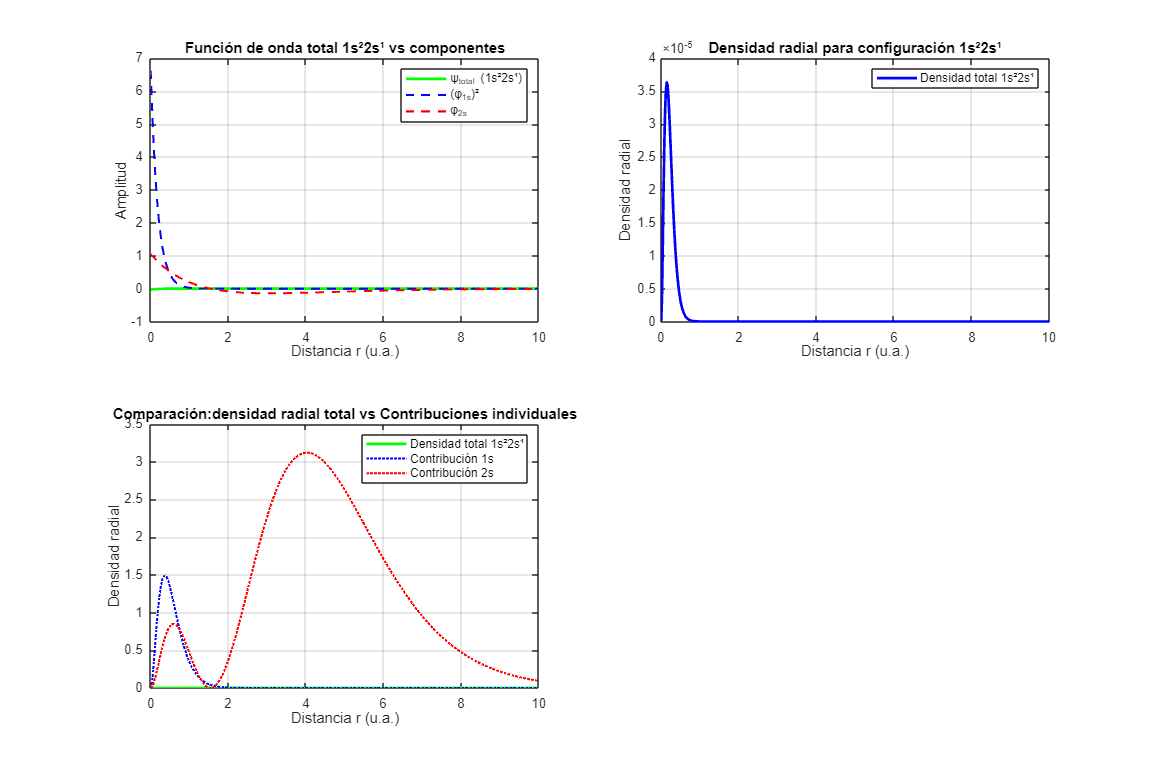




% Parámetros óptimos
alpha_opt = 2.75;  % Para electrones 1s
beta_opt = 1.3;    % Para electrón 2s (corregido)

% Definir rango de distancias
r = linspace(0, 10, 500);

% Funciones base hidrogenoides con parámetros sustituidos
phi_1s = sqrt(alpha_opt^3/pi) * exp(-alpha_opt * r);
phi_2s = sqrt(beta_opt^3/8) .* (2 - beta_opt * r) .* exp(-beta_opt * r / 2);

% Función de onda total para la configuración 1s²2s¹
% Para litio: dos electrones en 1s y uno en 2s
% Representación simplificada para visualización
psi_total = 0.154.*phi_1s.*-0.986.*phi_1s  .* 0.03.*phi_2s;  % 1s² × 2s¹

% Densidad radial total para la configuración completa
density_total = 4 * pi * r.^2 .* abs(psi_total).^2;  % Añadir abs() por seguridad

% También calcular densidades individuales para comparación
density_1s = 4 * pi * r.^2 .* phi_1s.^2;
density_2s = 4 * pi * r.^2 .* phi_2s.^2;

% === Gráfica integrada para configuración 1s²2s¹ ===
figure('Position', [100, 100, 1200, 800]);

% Subfigura 1: Función de onda total vs componentes
subplot(2,2,1);
plot(r, psi_total, 'g-', 'LineWidth', 2, 'DisplayName', 'ψ_{total} (1s²2s¹)');
hold on;
plot(r, phi_1s.^2, 'b--', 'LineWidth', 1.5, 'DisplayName', '(φ_{1s})²');
plot(r, phi_2s, 'r--', 'LineWidth', 1.5, 'DisplayName', 'φ_{2s}');
xlabel('Distancia r (u.a.)');
ylabel('Amplitud');
title('Función de onda total 1s²2s¹ vs componentes');
legend('show');
grid on;

% Subfigura 2: Densidad radial total
subplot(2,2,2);
plot(r, density_total, 'b-', 'LineWidth', 2, 'DisplayName', 'Densidad total 1s²2s¹');
xlabel('Distancia r (u.a.)');
ylabel('Densidad radial');
title('Densidad radial para configuración 1s²2s¹');
legend('show');
grid on;

% Subfigura 3: Comparación de densidades
subplot(2,2,3);
plot(r, density_total, 'g-', 'LineWidth', 2, 'DisplayName', 'Densidad total 1s²2s¹');
hold on;
plot(r, density_1s, 'b:', 'LineWidth', 1.5, 'DisplayName', 'Contribución 1s');
plot(r, density_2s, 'r:', 'LineWidth', 1.5, 'DisplayName', 'Contribución 2s');
xlabel('Distancia r (u.a.)');
ylabel('Densidad radial');
title('Comparación:densidad radial total vs Contribuciones individuales');
legend('show');
grid on;

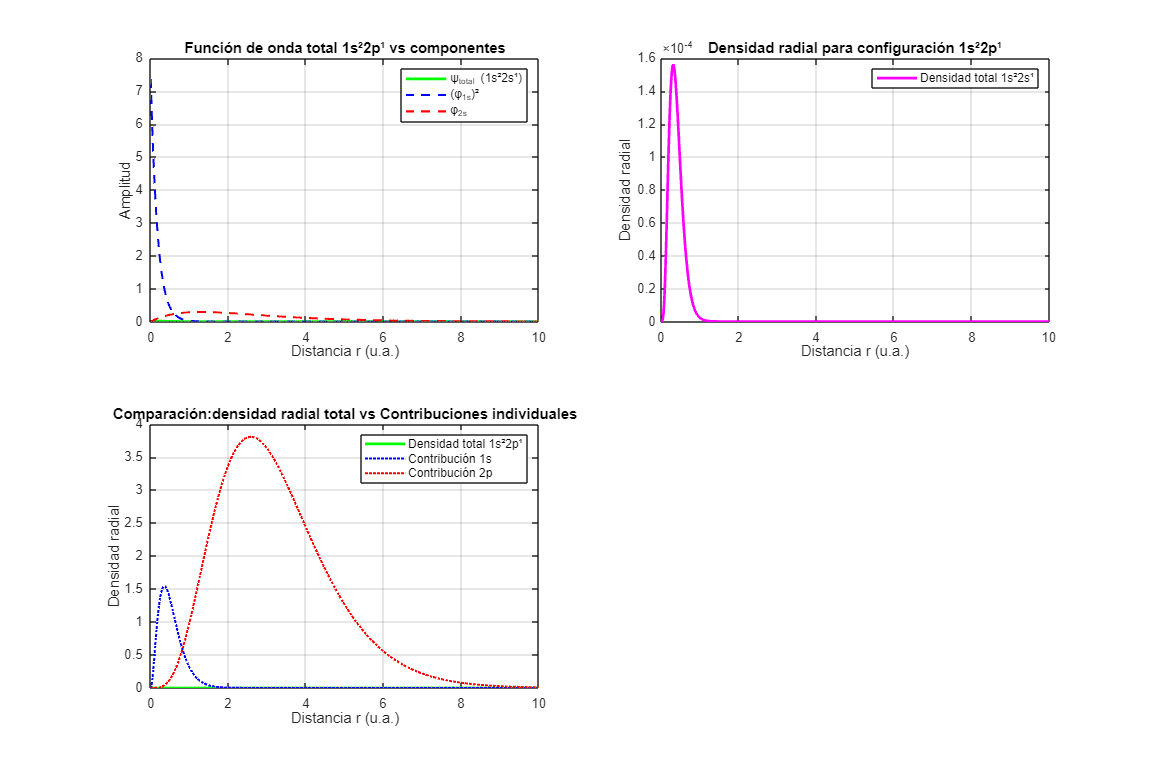



% Parámetros óptimos
alpha_opt = 2.85;  % Para electrones 1s
beta = 1.55;    % Para electrón 2s (corregido)

% Definir rango de distancias
r = linspace(0, 10, 500);

% Funciones base hidrogenoides con parámetros sustituidos
phi_1s = sqrt(alpha_opt^3/pi) * exp(-alpha_opt * r);
phi_2p = sqrt(beta^3/24) .* r .* beta .* exp(-beta * r / 2);

% Función de onda total para la configuración 1s²2s¹
% Para litio: dos electrones en 1s y uno en 2s
% Representación simplificada para visualización
psi_total = 0.51.* phi_1s.*0.85.* phi_1s.* 0.14.*phi_2p;  % 1s² × 2s¹

% Densidad radial total para la configuración completa
density_total = 4 * pi * r.^2 .* abs(psi_total).^2;  % Añadir abs() por seguridad

% También calcular densidades individuales para comparación
density_1s = 4 * pi * r.^2 .* phi_1s.^2;
density_2p = 4 * pi * r.^2 .* phi_2p.^2;

% === Gráfica integrada para configuración 1s²2s¹ ===
figure('Position', [100, 100, 1200, 800]);

% Subfigura 1: Función de onda total vs componentes
subplot(2,2,1);
plot(r, psi_total, 'g-', 'LineWidth', 2, 'DisplayName', 'ψ_{total} (1s²2s¹)');
hold on;
plot(r, phi_1s.^2, 'b--', 'LineWidth', 1.5, 'DisplayName', '(φ_{1s})²');
plot(r, phi_2p, 'r--', 'LineWidth', 1.5, 'DisplayName', 'φ_{2s}');
xlabel('Distancia r (u.a.)');
ylabel('Amplitud');
title('Función de onda total 1s²2p¹ vs componentes');
legend('show');
grid on;

% Subfigura 2: Densidad radial total
subplot(2,2,2);
plot(r, density_total, 'm-', 'LineWidth', 2, 'DisplayName', 'Densidad total 1s²2s¹');
xlabel('Distancia r (u.a.)');
ylabel('Densidad radial');
title('Densidad radial para configuración 1s²2p¹');
legend('show');
grid on;

% Subfigura 3: Comparación de densidades
subplot(2,2,3);
plot(r, density_total, 'g-', 'LineWidth', 2, 'DisplayName', 'Densidad total 1s²2p¹');
hold on;
plot(r, density_1s, 'b:', 'LineWidth', 1.5, 'DisplayName', 'Contribución 1s');
plot(r, density_2p, 'r:', 'LineWidth', 1.5, 'DisplayName', 'Contribución 2p');
xlabel('Distancia r (u.a.)');
ylabel('Densidad radial');
title('Comparación:densidad radial total vs Contribuciones individuales');
legend('show');
grid on;

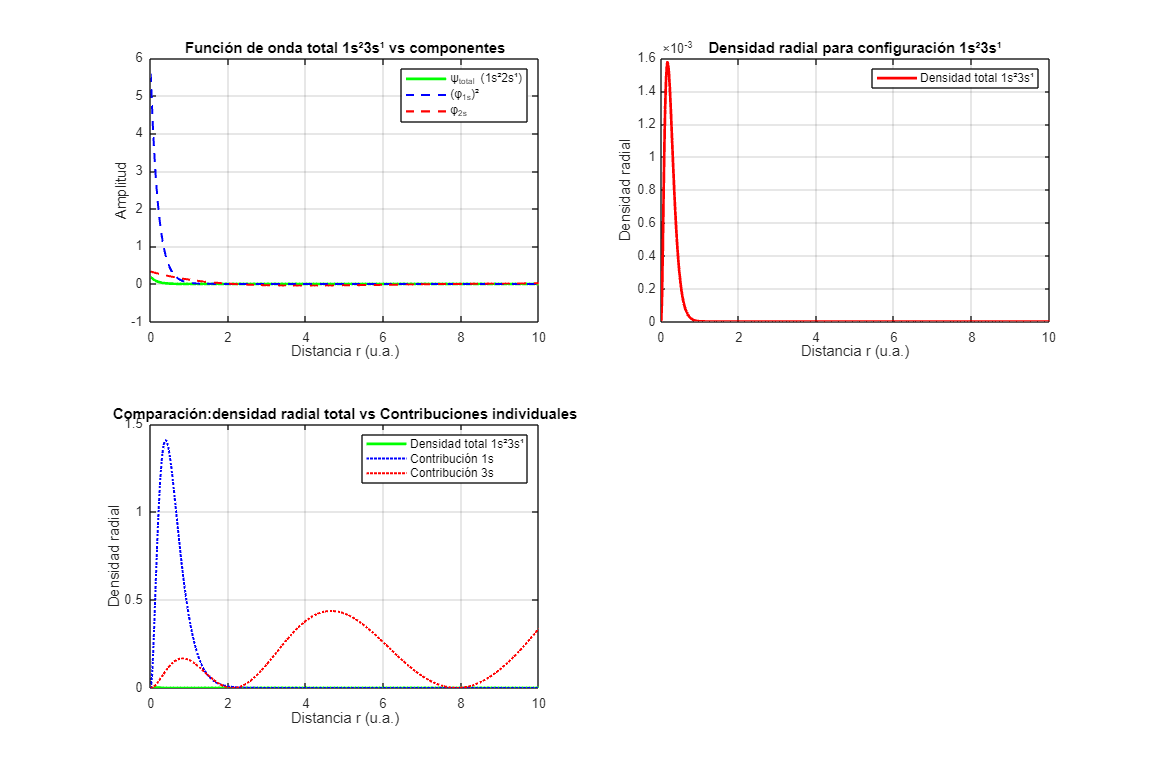



% Parámetros óptimos
alpha_opt = 2.6;  % Para electrones 1s
beta = 0.9;    % Para electrón 2s (corregido)

% Definir rango de distancias
r = linspace(0, 10, 500);

% Funciones base hidrogenoides con parámetros sustituidos
phi_1s = sqrt(alpha_opt^3/pi) * exp(-alpha_opt * r);
phi_3s = (2/27) * sqrt(beta^3/27) .* (27 - 18 * beta * r + 2 * beta^2 * r.^2) .* exp(-beta * r / 3);

% Función de onda total para la configuración 1s²2s¹
% Para litio: dos electrones en 1s y uno en 2s
% Representación simplificada para visualización
psi_total = -0.393.*phi_1s.*-0.3.*phi_1s.* 0.86.*phi_3s;  % 1s² × 2s¹

% Densidad radial total para la configuración completa
density_total = 4 * pi * r.^2 .* abs(psi_total).^2;  % Añadir abs() por seguridad

% También calcular densidades individuales para comparación
density_1s = 4 * pi * r.^2 .* phi_1s.^2;
density_3s = 4 * pi * r.^2 .* phi_3s.^2;

% === Gráfica integrada para configuración 1s²2s¹ ===
figure('Position', [100, 100, 1200, 800]);

% Subfigura 1: Función de onda total vs componentes
subplot(2,2,1);
plot(r, psi_total, 'g-', 'LineWidth', 2, 'DisplayName', 'ψ_{total} (1s²2s¹)');
hold on;
plot(r, phi_1s.^2, 'b--', 'LineWidth', 1.5, 'DisplayName', '(φ_{1s})²');
plot(r, phi_3s, 'r--', 'LineWidth', 1.5, 'DisplayName', 'φ_{2s}');
xlabel('Distancia r (u.a.)');
ylabel('Amplitud');
title('Función de onda total 1s²3s¹ vs componentes');
legend('show');
grid on;

% Subfigura 2: Densidad radial total
subplot(2,2,2);
plot(r, density_total, 'r-', 'LineWidth', 2, 'DisplayName', 'Densidad total 1s²3s¹');
xlabel('Distancia r (u.a.)');
ylabel('Densidad radial');
title('Densidad radial para configuración 1s²3s¹');
legend('show');
grid on;

% Subfigura 3: Comparación de densidades
subplot(2,2,3);
plot(r, density_total, 'g-', 'LineWidth', 2, 'DisplayName', 'Densidad total 1s²3s¹');
hold on;
plot(r, density_1s, 'b:', 'LineWidth', 1.5, 'DisplayName', 'Contribución 1s');
plot(r, density_3s, 'r:', 'LineWidth', 1.5, 'DisplayName', 'Contribución 3s');
xlabel('Distancia r (u.a.)');
ylabel('Densidad radial');
title('Comparación:densidad radial total vs Contribuciones individuales');
legend('show');
grid on;